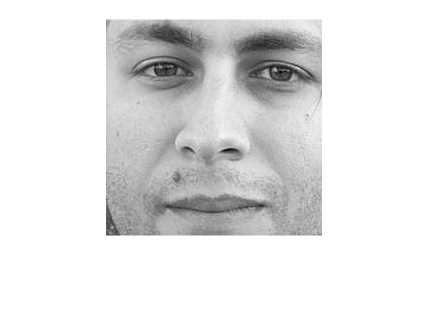

% Läs in bilden
img2 = imread("normalized_db0_2.jpg");

% Visa bilden 
% imshow(img2);

% Omvandla bilden till gråskala om den inte redan är det
if size(img2, 3) == 3
    gray_img2 = rgb2gray(img2);
else
    gray_img2 = img2;
end



% Visa den gråskaliga bilden 
imshow(gray_img2);


% 2. Omvandla bilden till en vektor av storlek N^2
image_vector = double(reshape(gray_img2, [], 1))

image_vector =    143
   146
   143
   140
   143
   144
   146
   152
   166
   169



% 3. Beräkna medelvärdet för bildvektorn
u = mean(image_vector)

u = 174.1156


% 4. Subtrahera medelvärdet för att centrera data
phi = image_vector - u

phi =   -31.1156
  -28.1156
  -31.1156
  -34.1156
  -31.1156
  -30.1156
  -28.1156
  -22.1156
   -8.1156
   -5.1156



% 5. Beräkna kovariansmatrisen
C = phi' * phi / (length(image_vector) - 1)

C = 1.6246e+03


% 6a. Beräkna egenvärden och egenvektorer för ATA
[Vi, Di] = eig(C)

Vi = 1

Di = 1.6246e+03


% 6b. Sortera egenvärdena och egenvektorerna i fallande ordning
[~, idx] = sort(diag(Di), 'descend')

idx = 1

Vi_sorted = Vi(:, idx)

Vi_sorted = 1


% 6c. Beräkna egenvektorerna ui för AAT
M = size(image_vector, 1) % Antal bilder

M = 47089

n = size(image_vector, 2) % Storlek på bildvektorn

n = 1

U = phi' * Vi_sorted % Egenvektorer för AAT

U =   -31.1156  -28.1156  -31.1156  -34.1156  -31.1156  -30.1156  -28.1156  -22.1156   -8.1156   -5.1156   -1.1156    1.8844    5.8844    9.8844   14.8844   18.8844   18.8844   20.8844   19.8844   14.8844    9.8844   10.8844   17.8844   24.8844   10.8844   11.8844   19.8844   22.8844   14.8844   11.8844   16.8844   20.8844   22.8844   17.8844   15.8844   16.8844   18.8844   18.8844   20.8844   22.8844   29.8844   25.8844   26.8844   32.8844   33.8844   30.8844   28.8844   30.8844   32.8844   32.8844



% Välj de bästa K egenvektorerna
K = 10; % Antal bästa egenvektorer att behålla
best_eigenvectors = U(:, 1:K)

best_eigenvectors =   -31.1156  -28.1156  -31.1156  -34.1156  -31.1156  -30.1156  -28.1156  -22.1156   -8.1156   -5.1156
